# Métodos Numéricos y Programación

*F. Pena*

## Tema 3. Métodos iterativos para la resolución de sistemas lineales 

### Método de Jacobi

La función jacobi implementa el método de resolución de sistemas triangulares por Jacobi, explicado en los apuntes de la materia.

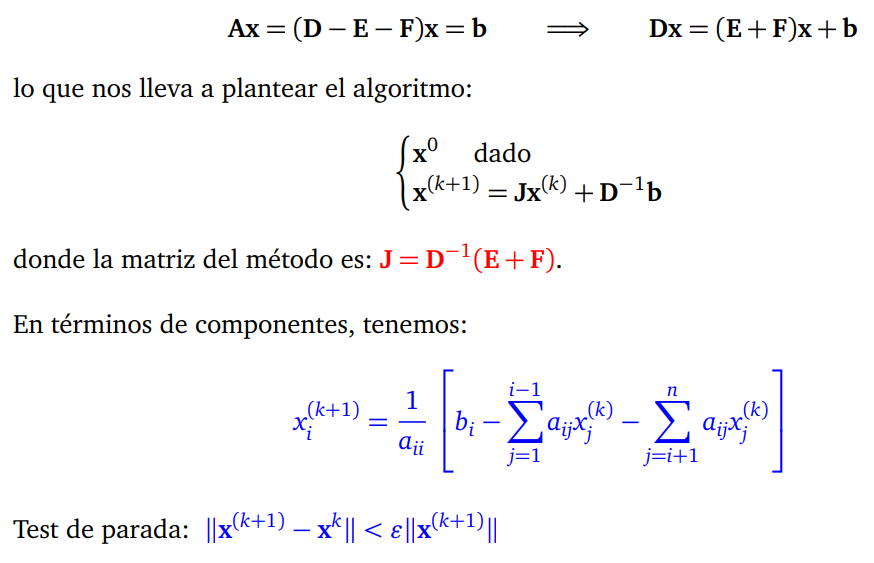

Veamos un ejemplo:

A = rand(5) + 5*eye(5); % diagonal dominante
b = rand(5, 1);
[x, conv, k] = jacobi(A, b);
%[x, conv, k] = jacobi(A, b, zeros(5,1), 1e-6, 100); 
if conv
    disp(['La solución converge después de ' num2str(k) ' iteraciones.'])
    disp('Solución aproximada:')
    disp(x)
else
    disp(['La solución no converge después de ' num2str(k) ' iteraciones.'])
end

La solución converge después de 16 iteraciones.


Solución aproximada:


    0.1279
    0.1047
    0.0449
    0.0753
   -0.0209



disp('Residuo:')

Residuo:


disp(A*x-b)

   1.0e-05 *

   -0.0464
   -0.0745
   -0.1004
   -0.1107
   -0.1162



Comparemos el número de iteraciones realizado según la escala por la que se multiplica el iterante inicial.

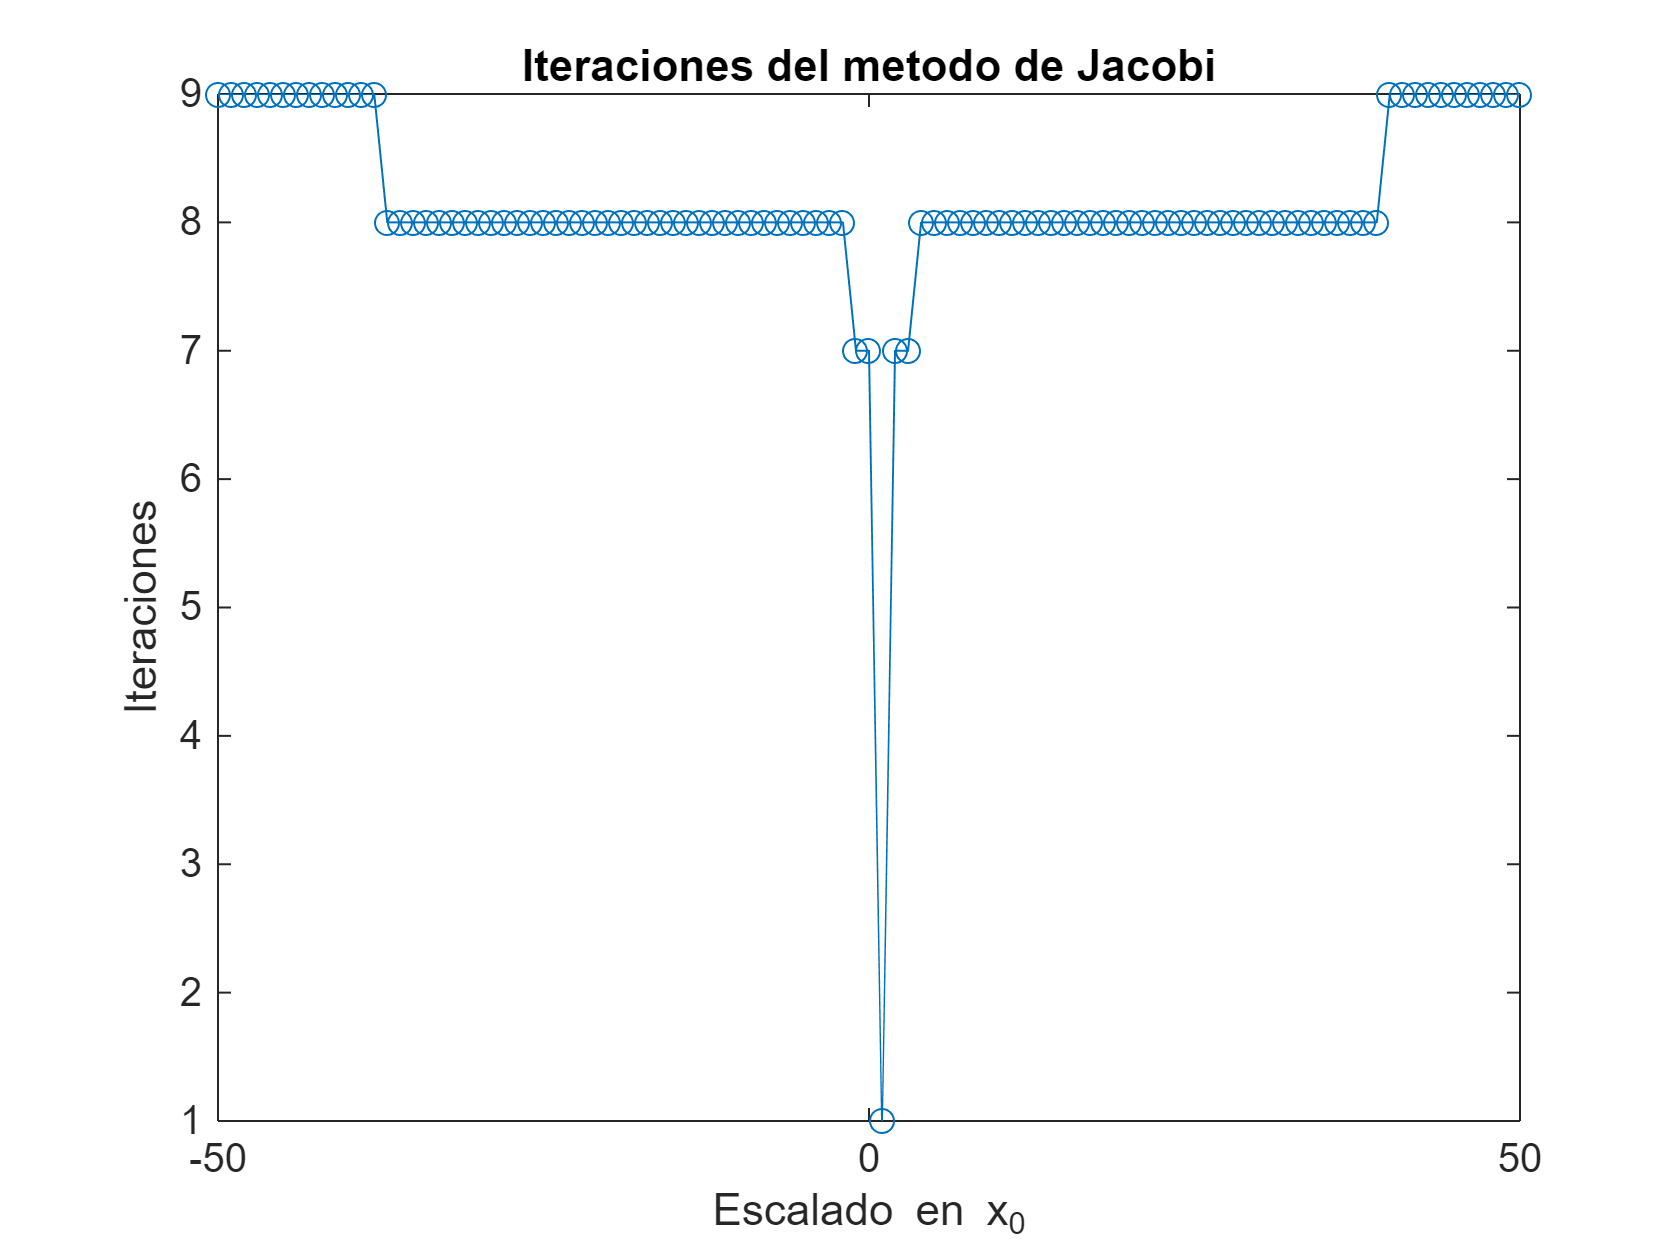

n = 100;
A = triu(rand(n)) + n * eye(n); % Diagonal dominante
x = rand(n, 1); % solucion verdadera
b = A * x; % b para dicah solucion

% Valores de escala
cval = -50:50; % Valores de c de 0.1 a 2
iter = zeros(length(cval), 1); % Almacenar número de iteraciones

% Iterar sobre diferentes valores de c
for j = 1:length(cval)
    [~, ~, iter(j)] = jacobi(A, b, cval(j)*x);
end
plot(cval, iter, '-o')
xlabel('Escalado en x_0');
ylabel('Iteraciones');
title('Iteraciones del metodo de Jacobi');

#### **Ejercicio de Gauss - Seidel**

Repite los cálculos anteriores para el método de Gauss - Seidel. Ten en cuenta que no es necesario guardar todo el iterante inicial en cada iteración del bucle. Usa matrices dispersas que sean diagonal dominantes.

## **Anexo. Funciones locales**

En Matlab, las funciones locales utilizadas en un *script*, van al final de éste.

function [x, conv, k] = jacobi(A, b, x0, tol, M)
    % jacobi - metodo iterativo de Jacobi para resolver sistemas de ecuaciones lineales
    %
    %   x = JACOBI(A, b) calcula una aproximación de la solución del sistema
    %   lineal Ax = b usando el método iterativo de Jacobi. Devuelve el
    %   vector de solución x.
    %
    %   [x, conv, k] = JACOBI(A, b, x0, tol, M) permite especificar:
    %     - x0: vector columna inicial para las iteraciones (por defecto, vector nulo).
    %     - tol: tolerancia para el test de parada (por defecto, 1e-5).
    %     - M: número máximo de iteraciones (por defecto, 50).
    %     - x: vector columna de solución (double).
    %     - conv: indicador de convergencia (booleano).
    %     - k: número de iteraciones realizadas (entero).    
    %
    %   Ejemplo de uso:
    %       A = rand(5) + 5*eye(5); % Aseguramos diagonal dominante
    %       b = rand(5, 1);
    %       x = jacobi(A, b); % Uso con valores predeterminados
    %       x = jacobi(A, b, zeros(5,1), 1e-6, 100); % Uso con valores específicos
   
    arguments
        A   (:,:) double {mustBeSquareMatrix(A)}                                % Matriz cuadrada
        b   (:,1) double {mustMatchNumRows(A, b)}                               % Vector columna con tamaño compatible
        x0  (:,1) double {mustMatchNumCols(A, x0)}       = zeros(size(A, 2), 1) % Vector columna inicial
        tol (1,1) double {mustBePositive}                = 1e-5                 % Tolerancia positiva
        M   (1,1) double {mustBeInteger, mustBePositive} = 50                   % Máximo de iteraciones
    end

    n = size(A, 2);
    x = x0;
    conv = false;

    for k = 1:M
        x_old = x; % solución anterior
        for i = 1:n
            x(i) = (b(i) - A(i, 1:i-1) * x_old(1:i-1) - A(i, i+1:n) * x_old(i+1:n)) / A(i, i);
        end
        if norm(x - x_old) < tol * norm(x)
            conv = true;
            return
        end
    end
end

% Función de validación personalizada: verifica que A sea cuadrada
function mustBeSquareMatrix(A)
    if size(A,1) ~= size(A,2)
        error('La matriz A debe ser cuadrada.');
    end
end

% Función de validación personalizada: verifica que el tamaño de b coincida con el número de filas de A
function mustMatchNumRows(A, b)
    if size(A, 1) ~= length(b)
        error('El tamaño de %s debe coincidir con el número de filas de A.', inputname(2));
    end
end

% Función de validación personalizada: verifica que el tamaño de x0 coincida con el número de columnas de A
function mustMatchNumCols(A, x0)
    if size(A, 2) ~= length(x0)
        error('El tamaño de %s debe coincidir con el número de columnas de A.', inputname(2));
    end
end